# Multi-Period Distributed Optimal Power Flow

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF", filesep) )
    addpath(genpath('functions\'))
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

T = 10;
delta_t = 0.25; % 15 minutes = 0.25 hours


macroItrMax = 20; % Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
tol = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
else
    error("Objective Function NOT recognized.")
end

plottingSpecificationFolder = strcat("plottingSpecifications", filesep);

tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};
for i = 1:length(tableNames)
    tableType = tableNames{i};
    tableName = strcat(tableType, "Table");
    table = readtable(fullfile(plottingSpecificationFolder, strcat(tableName, ".csv")));
    eval([tableType, ' = table2struct(table, "ToScalar", true);']);
end

timePeriods = transpose(1:T);
lambdaVals = generateLoadProfile(T, 1.0, 1.4);
% lambdaVals = generateLoadProfile(T, 1.0, 1.0);
pvCoeffVals = generatePVProfile(T, 0.7, 1.1, 0.6);
% pvCoeffVals = generatePVProfile(T, 1.0, 1.0, 1.0);
[PLosses, QLosses, PSubs, QSubs, solutionTimes] = deal( zeros(T, 1) );
[P12s, Q12s, V1s, PSaves] = deal( zeros(T, numAreas));
[P_ij, Q_ij, S_ij, l_ij, v_j, qD_j, B_j_pu, B_j, Pc_j_pu, Pc_j, Pd_j_pu, Pd_j, qB_j] = deal( zeros(T, numAreas, N));

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
N_Areas = zeros(numAreas, 1);
m_Areas = zeros(numAreas, 1);
nDER_Areas = zeros(numAreas, 1);
nBatt_Areas = zeros(numAreas, 1);

#### Start with the algorithm

*****
Checking for bus 2.
*****


row =            1
         145
         289
         433
         577
         721
         865
        1009
        1153
        1297


row =            1
         145
         289
         433
         577
         721
         865
        1009
        1153
        1297


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 3.
*****


row =            2
         146
         290
         434
         578
         722
         866
        1010
        1154
        1298


row =            2
         146
         290
         434
         578
         722
         866
        1010
        1154
        1298


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 4.
*****


row =            3
         147
         291
         435
         579
         723
         867
        1011
        1155
        1299


row =            3
         147
         291
         435
         579
         723
         867
        1011
        1155
        1299


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 5.
*****


row =            4
         148
         292
         436
         580
         724
         868
        1012
        1156
        1300


row =            4
         148
         292
         436
         580
         724
         868
        1012
        1156
        1300


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 6.
*****


row =            5
         149
         293
         437
         581
         725
         869
        1013
        1157
        1301


row =            5
         149
         293
         437
         581
         725
         869
        1013
        1157
        1301


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 7.
*****


row =            6
         150
         294
         438
         582
         726
         870
        1014
        1158
        1302


row =            6
         150
         294
         438
         582
         726
         870
        1014
        1158
        1302


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 8.
*****


row =            7
         151
         295
         439
         583
         727
         871
        1015
        1159
        1303


row =            7
         151
         295
         439
         583
         727
         871
        1015
        1159
        1303


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 9.
*****


row =            8
         152
         296
         440
         584
         728
         872
        1016
        1160
        1304


row =            8
         152
         296
         440
         584
         728
         872
        1016
        1160
        1304


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 10.
*****


row =            9
         153
         297
         441
         585
         729
         873
        1017
        1161
        1305


row =            9
         153
         297
         441
         585
         729
         873
        1017
        1161
        1305


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 11.
*****


row =           10
         154
         298
         442
         586
         730
         874
        1018
        1162
        1306


row =           10
         154
         298
         442
         586
         730
         874
        1018
        1162
        1306


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 12.
*****


row =           11
         155
         299
         443
         587
         731
         875
        1019
        1163
        1307


row =           11
         155
         299
         443
         587
         731
         875
        1019
        1163
        1307


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 13.
*****


row =           12
         156
         300
         444
         588
         732
         876
        1020
        1164
        1308


row =           12
         156
         300
         444
         588
         732
         876
        1020
        1164
        1308


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 14.
*****


row =           13
         157
         301
         445
         589
         733
         877
        1021
        1165
        1309


row =           13
         157
         301
         445
         589
         733
         877
        1021
        1165
        1309


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 15.
*****


row =           14
         158
         302
         446
         590
         734
         878
        1022
        1166
        1310


row =           14
         158
         302
         446
         590
         734
         878
        1022
        1166
        1310


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 16.
*****


row =           15
         159
         303
         447
         591
         735
         879
        1023
        1167
        1311


row =           15
         159
         303
         447
         591
         735
         879
        1023
        1167
        1311


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 17.
*****


row =           16
         160
         304
         448
         592
         736
         880
        1024
        1168
        1312


row =           16
         160
         304
         448
         592
         736
         880
        1024
        1168
        1312


lambdaVals =     1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 18.
*****


row =           17
         161
         305
         449
         593
         737
         881
        1025
        1169
        1313


row =           17
         161
         305
         449
         593
         737
         881
        1025
        1169
        1313


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 19.
*****


row = 10×1
          18
         162
         306
         450
         594
         738
         882
        1026
        1170
        1314


row = 10×1
          18
         162
         306
         450
         594
         738
         882
        1026
        1170
        1314


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 20.
*****


row = 10×1
          19
         163
         307
         451
         595
         739
         883
        1027
        1171
        1315


row = 10×1
          19
         163
         307
         451
         595
         739
         883
        1027
        1171
        1315


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 21.
*****


row = 10×1
          20
         164
         308
         452
         596
         740
         884
        1028
        1172
        1316


row = 10×1
          20
         164
         308
         452
         596
         740
         884
        1028
        1172
        1316


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 22.
*****


row = 10×1
          21
         165
         309
         453
         597
         741
         885
        1029
        1173
        1317


row = 10×1
          21
         165
         309
         453
         597
         741
         885
        1029
        1173
        1317


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 23.
*****


row = 10×1
          22
         166
         310
         454
         598
         742
         886
        1030
        1174
        1318


row = 10×1
          22
         166
         310
         454
         598
         742
         886
        1030
        1174
        1318


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 24.
*****


row = 10×1
          23
         167
         311
         455
         599
         743
         887
        1031
        1175
        1319


row = 10×1
          23
         167
         311
         455
         599
         743
         887
        1031
        1175
        1319


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 25.
*****


row = 10×1
          24
         168
         312
         456
         600
         744
         888
        1032
        1176
        1320


row = 10×1
          24
         168
         312
         456
         600
         744
         888
        1032
        1176
        1320


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 26.
*****


row = 10×1
          25
         169
         313
         457
         601
         745
         889
        1033
        1177
        1321


row = 10×1
          25
         169
         313
         457
         601
         745
         889
        1033
        1177
        1321


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 27.
*****


row = 10×1
          26
         170
         314
         458
         602
         746
         890
        1034
        1178
        1322


row = 10×1
          26
         170
         314
         458
         602
         746
         890
        1034
        1178
        1322


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 28.
*****


row = 10×1
          27
         171
         315
         459
         603
         747
         891
        1035
        1179
        1323


row = 10×1
          27
         171
         315
         459
         603
         747
         891
        1035
        1179
        1323


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 29.
*****


row = 10×1
          28
         172
         316
         460
         604
         748
         892
        1036
        1180
        1324


row = 10×1
          28
         172
         316
         460
         604
         748
         892
        1036
        1180
        1324


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 30.
*****


row = 10×1
          29
         173
         317
         461
         605
         749
         893
        1037
        1181
        1325


row = 10×1
          29
         173
         317
         461
         605
         749
         893
        1037
        1181
        1325


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 31.
*****


row = 10×1
          30
         174
         318
         462
         606
         750
         894
        1038
        1182
        1326


row = 10×1
          30
         174
         318
         462
         606
         750
         894
        1038
        1182
        1326


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 32.
*****


row = 10×1
          31
         175
         319
         463
         607
         751
         895
        1039
        1183
        1327


row = 10×1
          31
         175
         319
         463
         607
         751
         895
        1039
        1183
        1327


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 33.
*****


row = 10×1
          32
         176
         320
         464
         608
         752
         896
        1040
        1184
        1328


row = 10×1
          32
         176
         320
         464
         608
         752
         896
        1040
        1184
        1328


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 34.
*****


row = 10×1
          33
         177
         321
         465
         609
         753
         897
        1041
        1185
        1329


row = 10×1
          33
         177
         321
         465
         609
         753
         897
        1041
        1185
        1329


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0067

*****
Checking for bus 35.
*****


row = 10×1
          34
         178
         322
         466
         610
         754
         898
        1042
        1186
        1330


row = 10×1
          34
         178
         322
         466
         610
         754
         898
        1042
        1186
        1330


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 36.
*****


row = 10×1
          35
         179
         323
         467
         611
         755
         899
        1043
        1187
        1331


row = 10×1
          35
         179
         323
         467
         611
         755
         899
        1043
        1187
        1331


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0.0133

*****
Checking for bus 37.
*****


row = 10×1
          36
         180
         324
         468
         612
         756
         900
        1044
        1188
        1332


row = 10×1
          36
         180
         324
         468
         612
         756
         900
        1044
        1188
        1332


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 38.
*****


row = 10×1
          37
         181
         325
         469
         613
         757
         901
        1045
        1189
        1333


row = 10×1
          37
         181
         325
         469
         613
         757
         901
        1045
        1189
        1333


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 39.
*****


row = 10×1
          38
         182
         326
         470
         614
         758
         902
        1046
        1190
        1334


row = 10×1
          38
         182
         326
         470
         614
         758
         902
        1046
        1190
        1334


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 40.
*****


row = 10×1
          39
         183
         327
         471
         615
         759
         903
        1047
        1191
        1335


row = 10×1
          39
         183
         327
         471
         615
         759
         903
        1047
        1191
        1335


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

*****
Checking for bus 41.
*****


row = 10×1
          40
         184
         328
         472
         616
         760
         904
        1048
        1192
        1336


row = 10×1
          40
         184
         328
         472
         616
         760
         904
        1048
        1192
        1336


lambdaVals = 1×10
    1.0000    1.1000    1.2000    1.3000    1.4000    1.4000    1.3000    1.2000    1.1000    1.0000


ans = 0

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0        2761    0.000000e+00     9.752e-02     1.000e+00     0.000e+00     2.401e-02  
    1        5522    5.482956e-05     1.442e-01     1.000e+00     2.660e+00     9.608e+06  
    2        8283    8.700513e-03     3.419e-03     1.000e+00     5.527e-01     1.037e-01  
    3       11044    8.895265e-03     1.466e-05     1.000e+00     2.804e-02     9.609e-03  
    4       13805    8.768124e-03     4.624e-06     1.000e+00     1.758e-02     4.990e-03  
    5       16566    8.282183e-03     7.516e-05     1.000e+00     6.977e-02     4.312e-03  
    6       19327    6.329107e-03     1.360e-03     1.000e+00     2.964e-01     2.054e-03  
    7       22088    5.013976e-03     1.301e-03     1.000e+00     2.837e-01     4.283e-03  
    8       24849    4.740430e-03     2.211e-04     1.000e+00     1.146e-01     3.

x = 2760×1
    0.0851
    0.0851
    0.0067
    0.0334
    0.0133
    0.0200
    0.0133
    0.0317
    0.0250
    0.0333


fval = 0.0044

areaInfo = struct with fields:
                        Area: 1
                      N_Area: 41
                      m_Area: 40
                     fb_Area: [40×1 double]
                     tb_Area: [40×1 double]
                    P_L_Area: [41×1 double]
                    Q_L_Area: [41×1 double]
                    Q_C_Area: [41×1 double]
                  P_der_Area: [41×1 double]
                  S_der_Area: [41×1 double]
              S_battMax_Area: [41×1 double]
              P_battMax_Area: [41×1 double]
              Emax_batt_Area: [41×1 double]
          busesWithDERs_Area: [23×1 double]
                   nDER_Area: 23
         busesWithBatts_Area: [23×1 double]
                  nBatt_Area: 23
         S_onlyDERbuses_Area: [23×1 double]
         P_onlyDERbuses_Area: [23×1 double]
     S_onlyBattBusesMax_Area: [23×1 double]
     P_onlyBattBusesMax_Area: [23×1 double]
     E_onlyBattBusesMax_Area: [23×1 double]
    lb_Pc_onlyBattBuses_Area: [23×1 double]
    ub_Pc_onl

T = 10

Checking for SCD for Area 1


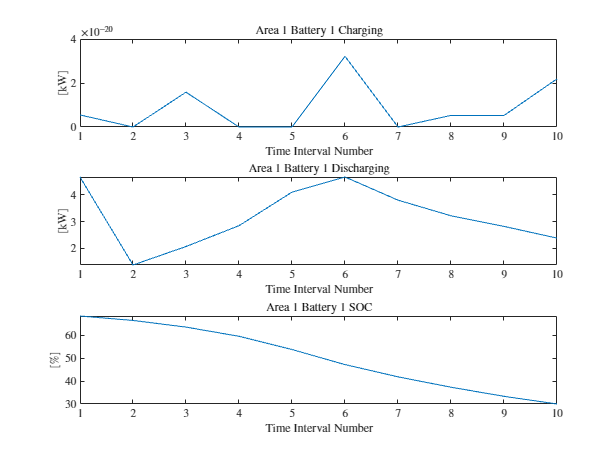

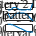

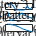

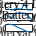

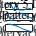

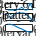

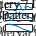

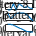

Unable to perform assignment because the left and right sides have a different number of elements.

Error in LinEqualities (line 157)
        beq(row) = lambdaVals*P_L_Area(j);

Error in NL_OPF_dist2 (line 140)
    [Aeq, beq, lb, ub, x0, areaInfo] = Lin

% for t = 1:T
    if logging && verbose
        error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
    elseif logging && ~verbose
        fileOpenedFlag = true;
        % if t == 1
            fid = fopen(saveLocationFilename, 'w');
        % else
            % fid = fopen(saveLocationFilename, 'a');
        % end
    elseif ~logging
        logging = verbose;
        fid = 1;
    end
    
    % if t == 1
        myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
    "will be run.\n", T, delta_t*60, delta_t*T);
    % end

    myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
    keepRunningIterations = true;
    macroItr = 1;
    time_dist = zeros(macroItrMax, numAreas);
    macroIterationPLosses = zeros(macroItrMax, numAreas);
    macroIterationQLosses = zeros(macroItrMax, numAreas);
    macroIterationPSaves = zeros(macroItrMax, numAreas);
    ResidualMax = zeros(macroItrMax, 1);
    v2_parent = 1.03^2*ones(numAreas, 1);
    % lambdaVal = lambdaVals(t);
    % pvCoeff = pvCoeffVals(t);
    Se_iter = zeros(macroItrMax, numAreas);
    V_iter = zeros(macroItrMax, N, numUniqueParents);
    S_allRelationships = CBTable.S_childArea;
    S_parent = zeros(numAreas, 1);
    S_Areas = zeros(N, numAreas);
    v2_Areas = zeros(N, numAreas);
    
    t = 1;
    while keepRunningIterations
        for Area = 1:numAreas
            
            v2_parent_Area = v2_parent(Area);
            S_childAreas = S_allRelationships(CBTable.parentArea == Area);
    
            isLeaf_Area = isLeaf(Area);
            isRoot_Area = isRoot(Area);
            numChildAreas_Area = numChildAreas(Area);
            
            B0Vals_pu_Area = B_j_pu(t, Area, :);
    
            [xVals_Area, B0Vals_pu_Area, ...
                macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, macroItr, time_dist, ...
                N_Area, m_Area, nDER_Area, nBatt_Area, ...
                busDataTable_Area, branchDataTable_Area] = ...
                ...
                NL_OPF_dist2(v2_parent_Area, S_childAreas, B0Vals_pu_Area, ...
                lambdaVals, pvCoeffVals, ...
                Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, numAreas, ...
                macroIterationPLosses, macroIterationQLosses, ...
                macroIterationPSaves, ...
                macroItr, time_dist, t, T,   ...
                CBTable, 'verbose', verbose, 'saveToFile', true, 'logging', logging);
            
            N_Areas(Area) = N_Area;
            m_Areas(Area) = m_Area;
            nDER_Areas(Area) = nDER_Area;
            nBatt_Areas(Area) = nBatt_Area;

            numVarsFull = [m_Area, m_Area, m_Area, N_Area, nDER_Area, nBatt_Area, nBatt_Area, nBatt_Area, nBatt_Area];
            ranges_Full = generateRangesFromValues(numVarsFull);

            indices_P = ranges_Full{1};
            indices_Q = ranges_Full{2};
            indices_l = ranges_Full{3};
            indices_vAll = ranges_Full{4};
            indices_v = indices_vAll(2:end);
            indices_qD = ranges_Full{5};
            indices_B = ranges_Full{6};
            indices_Pc = ranges_Full{7};
            indices_Pd = ranges_Full{8};
            indices_qB = ranges_Full{9};
            
            P_Area = xVals_Area(indices_P); %m_Areax1
            Q_Area = xVals_Area(indices_Q); %m_Areax1
            S_Area = complex(P_Area, Q_Area); %m_Areax1
            l_Area = xVals_Area(indices_l);
            vFull_Area = xVals_Area(indices_vAll); %N_Areax1
            v2_Area = vFull_Area;
            qD_Area = xVals_Area(indices_qD);
            B_Area = xVals_Area(indices_B);
            Pd_Area = xVals_Area(indices_Pd);
            Pc_Area = xVals_Area(indices_Pc);
            qB_Area = xVals_Area(indices_qB);
            
            S_parent(Area) = S_Area(1);
            
            v2_Areas(1:N_Area, Area) = vFull_Area;
            S_Areas(1:m_Area, Area) = S_Area;   % Storing all the S flow of the Area
    
        end
        
        
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            S12_fromParent = S_Areas(parentAreaConnectingBus - 1, parAr);
            S12_intoChild = S_parent(chAr);
    
            delta_S12 = S12_fromParent - S12_intoChild;
    
            v2_parentSide = v2_Areas(parentAreaConnectingBus, parAr);
            v2_childSide = v2_parent(chAr);
    
            delta_v2 = v2_parentSide - v2_childSide;
    
            Residual_Area = [delta_S12; delta_v2];
            
            if max(abs(Residual_Area)) > ResidualMax(macroItr+1)
                ResidualMax(macroItr+1) = max(abs(Residual_Area));
            end
    
        end
        
        if macroItr > macroItrMax
            % keepRunningIterations = false;
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif ResidualMax(macroItr+1) < tol
            myfprintf(logging, fid, "Time Period = %d, Converged in %d macro-iterations!\n", t, macroItr);
            keepRunningIterations = false;
            ResidualMax = ResidualMax(1:macroItr);
    
        else
            myfprintf(logging, fid, "Time Period = %d, Still yet to converge after %d macro-iterations, continuing.\n", t, macroItr)
            %Communication-
            
            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);
                V_iter(macroItr+1, busParTo, parAr) = v2_Areas(busParTo, parAr) ;
                Se_iter(macroItr+1,chAr) = S_parent(chAr);
    
                if macroItr > 2
                    v2_parent(chAr) = a(2)*V_iter(macroItr-1, busParTo, parAr)+...
                        a(1)*V_iter(macroItr, busParTo, parAr)+...
                        (1-sum(a))*v2_Areas(busParTo, parAr) ;
    
                    S_allRelationships(relationshipNum) = a(2)*Se_iter(macroItr-1, chAr)+...
                        a(1)*Se_iter(macroItr, chAr)+...
                        (1-sum(a))*S_parent(chAr);
                else
    
                    v2_parent(chAr) = v2_Areas(busParTo, parAr);
                    S_allRelationships(relationshipNum) = S_parent(chAr);
    
                end
    
            end
    
            macroItr = macroItr + 1;
    
        end
         
        % S12 = transpose(S_Areas(1, :));
        % P12s(t, :) = kVA_B*real(S12);
        % Q12s(t, :) = kVA_B*imag(S12);
        % V1s(t, :) = sqrt(transpose(v2_Areas(1, :)));
        % PSaves(t, :) = macroIterationPSaves(macroItr, :);
    
    end

    
    N_ParentArea_Max = max(N_Areas(uniqueParents));
    Se_iter = Se_iter(1:macroItr, :);
    V_iter = V_iter(1:macroItr, 1:N_ParentArea_Max, uniqueParents);
    
    macroIterationPLosses = macroIterationPLosses(1:macroItr, :);
    macroIterationQLosses = macroIterationQLosses(1:macroItr, :);
    time_dist = time_dist(1:macroItr, :);
    
    % PLosses(t) = kVA_B * sum(macroIterationPLosses(macroItr, :)); %sum over each row
    % QLosses(t) = kVA_B * sum(macroIterationQLosses(macroItr, :));
    % PSubs(t) = P12s(t, 1);
    % QSubs(t) = Q12s(t, 1);
    % solutionTimes(t) = sum(time_dist(macroItr, :));

    % postProcessResults(T, N, numAreas, N_Areas, isRoot, v2_Areas, actualBusNums, ...
    %     macroIterationPLosses, t, macroItr, time_dist, kVA_B, displaySimulationResultPlots, ...
    %     ResidualMax, saveSimulationResultPlots, systemName, S_Areas, start, generateTextFilesForResults);

% end

if fileOpenedFlag
    fclose(fid);
end
grandTotalTime = toc(start)


% % Create a cell array containing the names of the structures
% tableNames = {'xSys', 'ySys', 'yArs', 'yNodes'};
% 
% % Loop through each structure
% for structIndex = 1:length(tableNames)
%     structName = tableNames{structIndex};
%     currentStruct = eval(structName); % Access the structure by its name
% 
%     % Loop through each variable name in the 'VarNames' field
%     for varIndex = 1:length(currentStruct.VarNames)
%         varName = currentStruct.VarNames{varIndex}; % Get the variable name
% 
%         % Use eval to get the value of the variable whose name is stored in varName
%         % and assign it to the 'Vars' field in the current structure
%         currentStruct.Vars{varIndex} = eval(varName);
%     end
% 
%     % Assign the modified structure back to its original variable name
%     eval([structName, ' = currentStruct;']);
% end



% results = struct();
% results.xSys = xSys;
% results.ySys = ySys;
% results.yArs = yArs;
% results.yNodes = yNodes;
% results.objFun = strObjectiveFunction;
% results.suffixObj = suffixObj;


plotSimulationResults(results, 'verbose', true);